# Test Frequency Domain

close all
clear variables
clc

## display properties

set(0, 'DefaultAxesFontname', 'Arial CE');
font_size = 16;
set(0, 'DefaultAxesFontsize', font_size);
set(0, 'defaulttextfontname', 'Arial CE');
set(0, 'defaulttextfontsize', font_size);
set(0, 'defaultfigurecolor', 'w');

## BODY

## set the 'nirfasterroot' as current folder

cd(nirfasterroot);

## test FD on standard mesh:

## forward data 2D

mesh = load_mesh('circle2000_86_stnd');

Fixed sources
Sources integration functions loaded
Fixed detectors
Detectors integration functions loaded


## continuous wave 2D

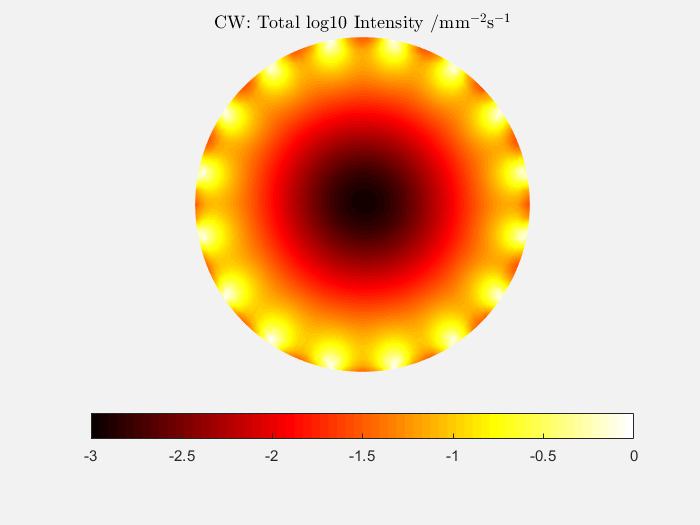

data_cw = femdata_FD(mesh,0);
% plot intensity integrated @ all sources
plotimage(mesh,log10(abs(sum(data_cw.phi,2))));
title('CW: Total log10 Intensity /mm$^{-2}$s$^{-1}$','Interpreter','latex')
set(gca,'CLim',[-3 0])

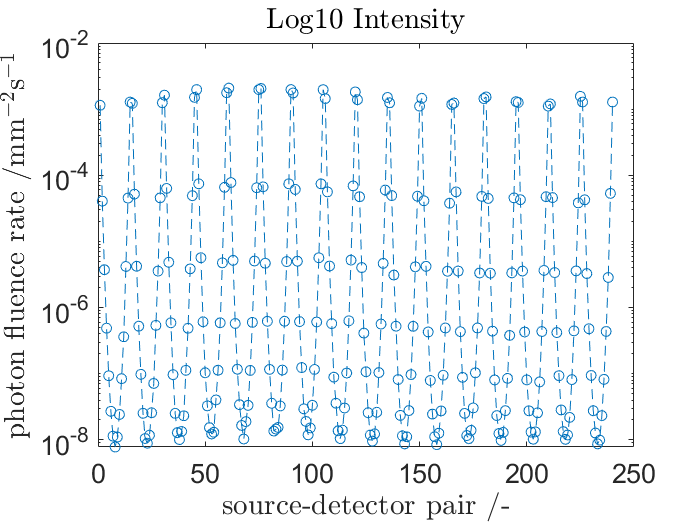


% plot intensity for source-detector pairs
figure('Name',mesh.name)
semilogy(data_cw.amplitude,'o--')
title('Log10 Intensity','Interpreter','latex');
xlabel('source-detector pair /-','Interpreter','latex')
ylabel('photon fluence rate /mm$^{-2}$s$^{-1}$','Interpreter','latex')

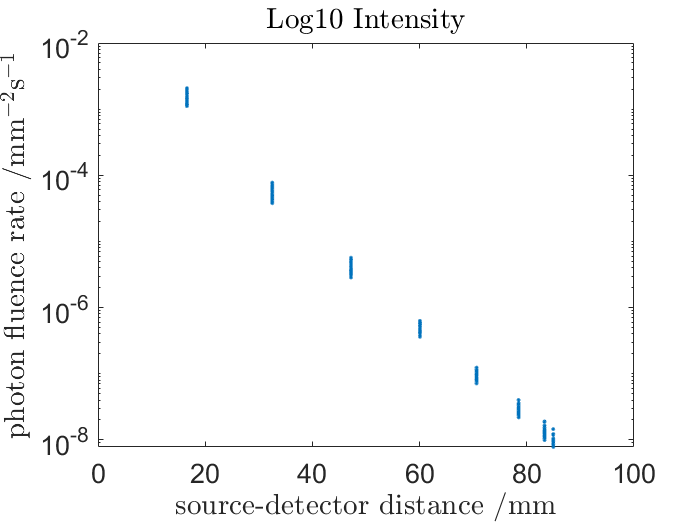


%calcuate source-detector distances
sd_distances = sqrt(sum((mesh.meas.coord(mesh.link(:,2),:) - mesh.source.coord(mesh.link(:,1),:)).^2,2));
% plot intensity vs source-detector distances
figure('Name',mesh.name)
semilogy(sd_distances, data_cw.amplitude,'.')
title('Log10 Intensity','Interpreter','latex');
xlabel('source-detector distance /mm','Interpreter','latex')
ylabel('photon fluence rate /mm$^{-2}$s$^{-1}$','Interpreter','latex')

## frequency domain 2D

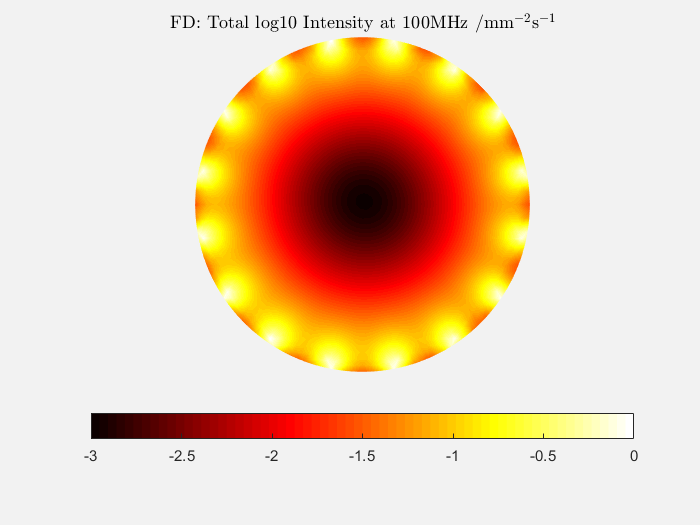

data_FD = femdata_FD(mesh,100e6);
% plot intensity integrated @ all sources
plotimage(mesh,log10(abs(sum(data_FD.phi,2))));
title('FD: Total log10 Intensity at 100MHz /mm$^{-2}$s$^{-1}$','Interpreter','latex');
set(gca,'CLim',[-3 0])

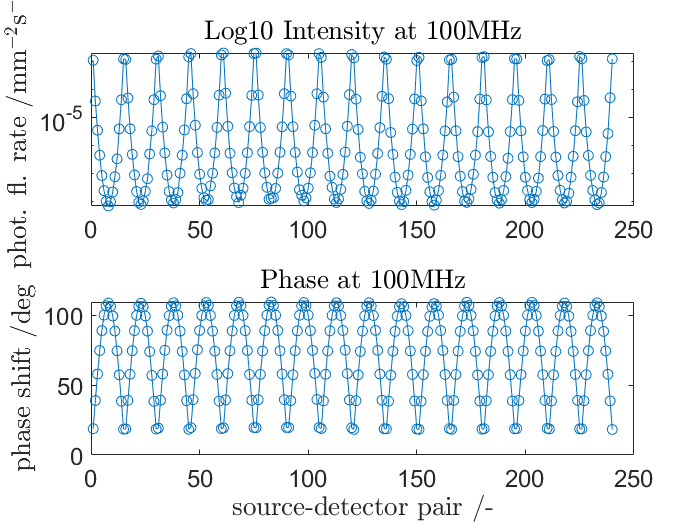


figure('Name',mesh.name)
% plot log intensity at source-detector pairs
subplot(2,1,1); semilogy(data_FD.amplitude,'o-')
title('Log10 Intensity at 100MHz','Interpreter','latex');
ylabel('phot. fl. rate /mm$^{-2}$s$^{-1}$','Interpreter','latex')
% plot phase shift at source-detector pairs
subplot(2,1,2); plot(data_FD.phase,'o-')
title('Phase at 100MHz','Interpreter','latex');
xlabel('source-detector pair /-','Interpreter','latex')
ylabel('phase shift /deg','Interpreter','latex')

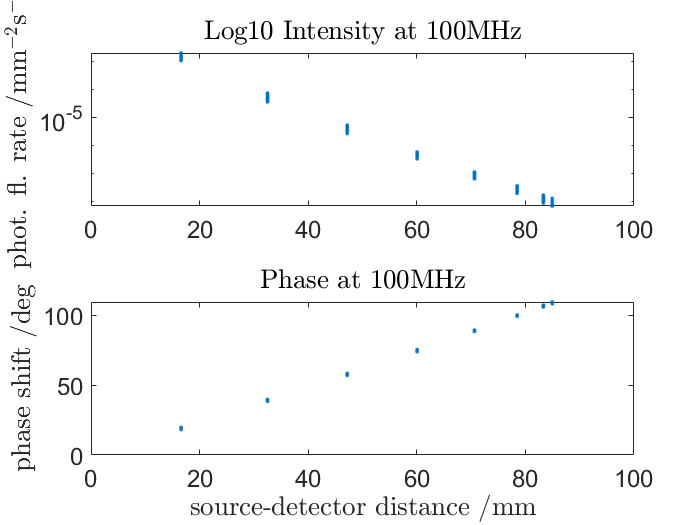


figure('Name',mesh.name)
% plot log intensity vs source-detector distance
subplot(2,1,1); semilogy(sd_distances, data_FD.amplitude,'.')
title('Log10 Intensity at 100MHz','Interpreter','latex');
ylabel('phot. fl. rate /mm$^{-2}$s$^{-1}$','Interpreter','latex')
% plot phase vs source-detector distance
subplot(2,1,2); plot(sd_distances, data_FD.phase,'.')
title('Phase at 100MHz','Interpreter','latex');
xlabel('source-detector distance /mm','Interpreter','latex')
ylabel('phase shift /deg','Interpreter','latex')

## Jacobian 2D

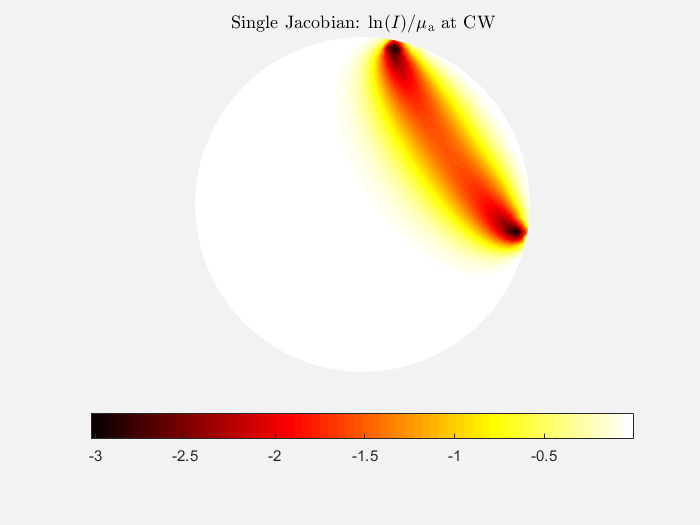

%continuous wave
[J_cw,~] = jacobian_FD(mesh,0);
plotimage(mesh,J_cw.complete(12,:));
title('Single Jacobian: $\ln(I)/\mu_{\mathrm{a}}$ at CW','Interpreter','latex');

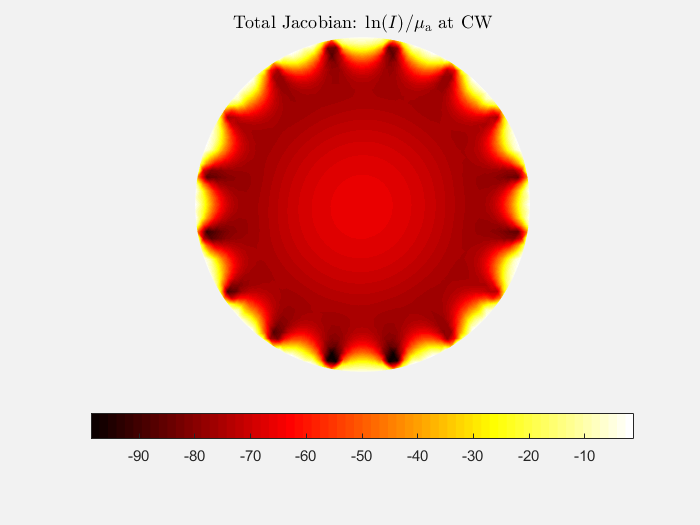

plotimage(mesh,sum(J_cw.complete,1));
title('Total Jacobian: $\ln(I)/\mu_{\mathrm{a}}$ at CW','Interpreter','latex');

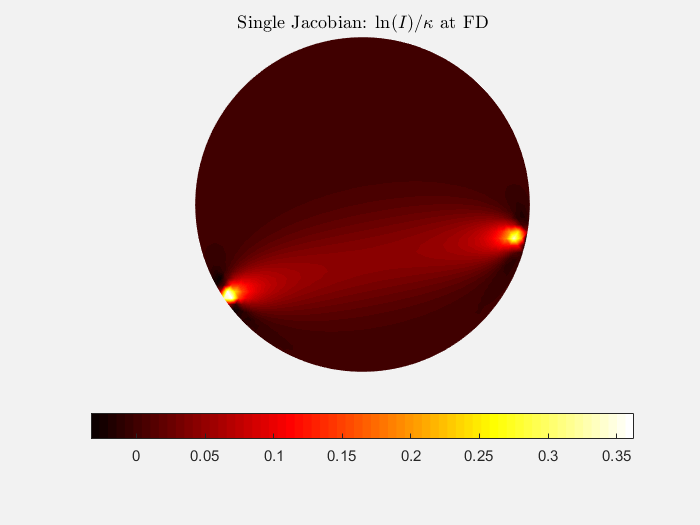


%frequency domain
[J_FD,~] = jacobian_FD(mesh,100e6);
plotimage(mesh,J_FD.complete(11,1:end/2));
title('Single Jacobian: $\ln(I)/\kappa$ at FD','Interpreter','latex');

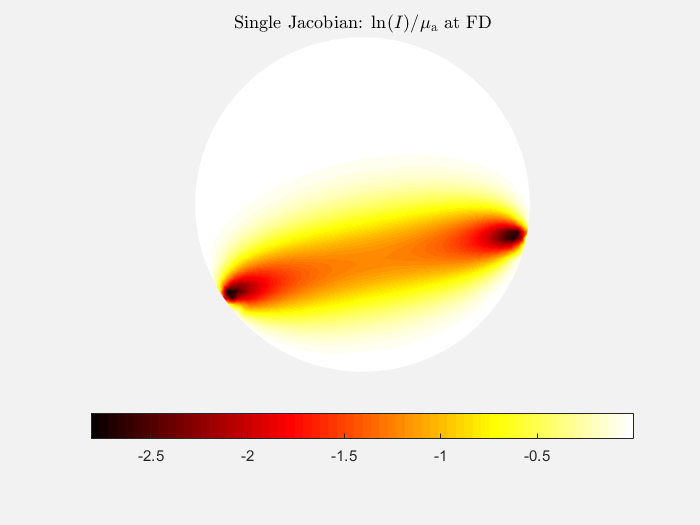

plotimage(mesh,J_FD.complete(11,end/2+1:end));
title('Single Jacobian: $\ln(I)/\mu_{\mathrm{a}}$ at FD','Interpreter','latex');

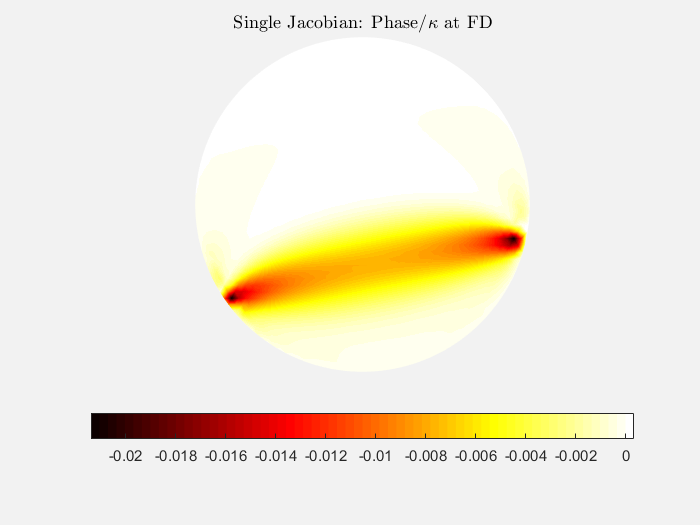

plotimage(mesh,J_FD.complete(12,1:end/2));
title('Single Jacobian: Phase/$\kappa$ at FD','Interpreter','latex');

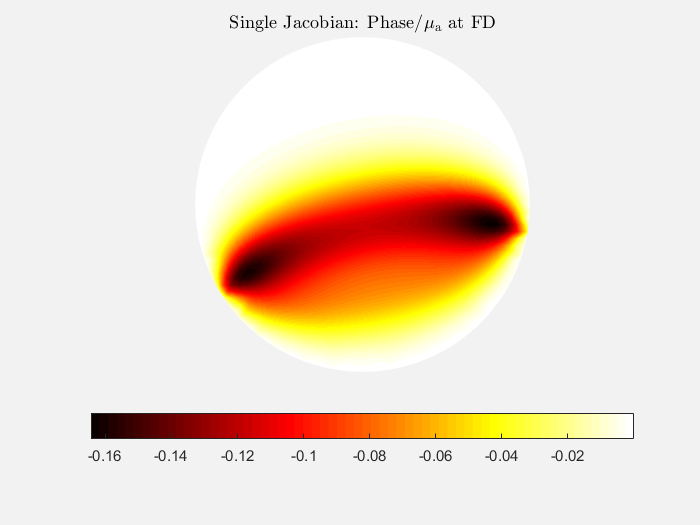

plotimage(mesh,J_FD.complete(12,end/2+1:end));
title('Single Jacobian: Phase/$\mu_{\mathrm{a}}$ at FD','Interpreter','latex');

## forward data 3D

mesh = load_mesh('cylinder_stnd');

Sources integration functions loaded
Detectors integration functions loaded


## continuous wave 3D

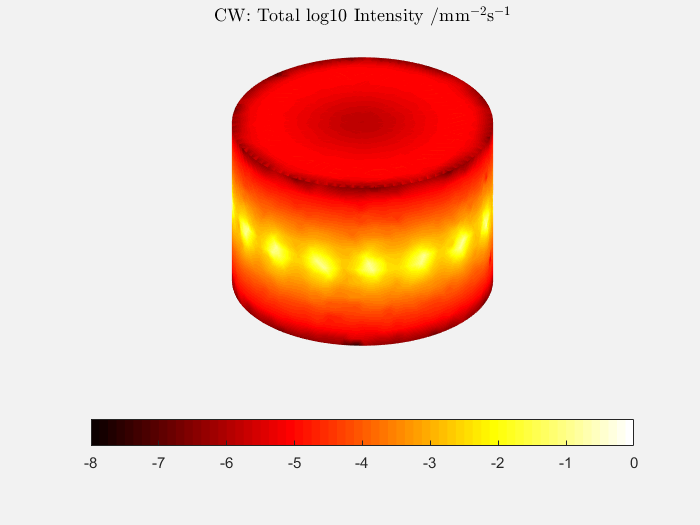

data_cw = femdata_FD(mesh,0);
plotimage(mesh,log10(abs(sum(data_cw.phi,2))));
title('CW: Total log10 Intensity /mm$^{-2}$s$^{-1}$','Interpreter','latex')
set(gca,'CLim',[-8 0])

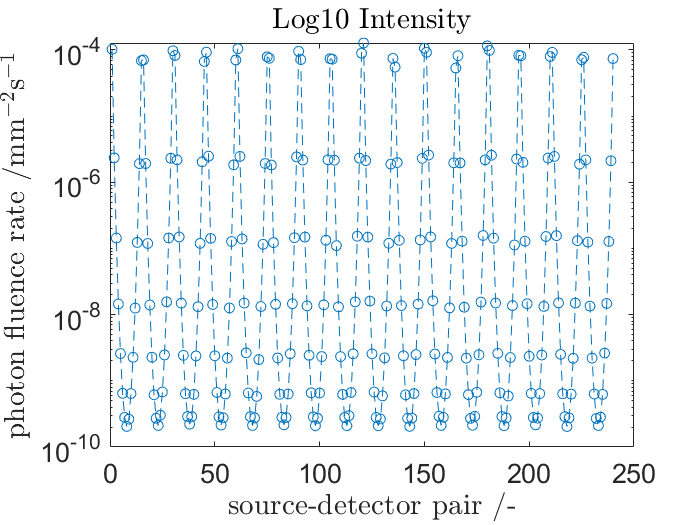


figure('Name',mesh.name)
%plot intensities at source-detector pairs
semilogy(data_cw.amplitude,'o--')
title('Log10 Intensity','Interpreter','latex');
xlabel('source-detector pair /-','Interpreter','latex')
ylabel('photon fluence rate /mm$^{-2}$s$^{-1}$','Interpreter','latex')

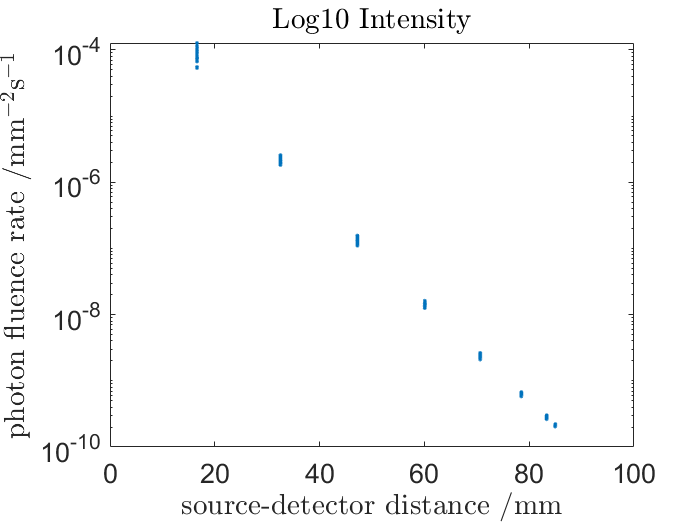


%calcuate source-detector distances
sd_distances = sqrt(sum((mesh.meas.coord(mesh.link(:,2),:) - mesh.source.coord(mesh.link(:,1),:)).^2,2));
% plot intensity vs source-detector distances
figure('Name',mesh.name)
semilogy(sd_distances, data_cw.amplitude,'.')
title('Log10 Intensity','Interpreter','latex');
xlabel('source-detector distance /mm','Interpreter','latex')
ylabel('photon fluence rate /mm$^{-2}$s$^{-1}$','Interpreter','latex')

## frequency domain 3D

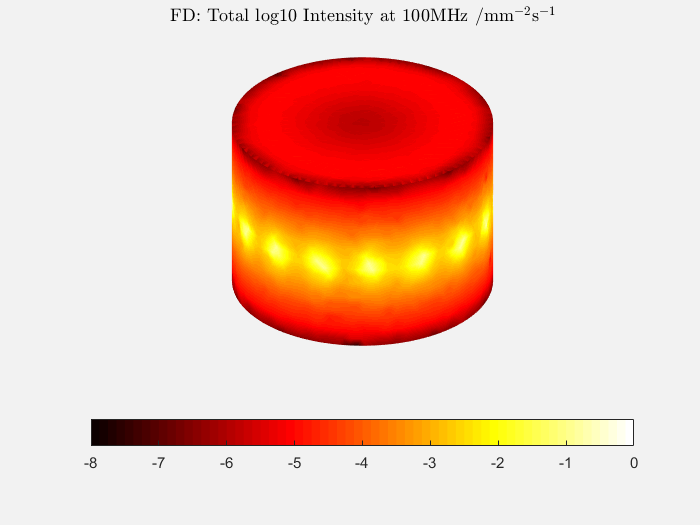

data_FD = femdata_FD(mesh,100e6);
% plot intensity integrated @ all sources
plotimage(mesh,log10(abs(sum(data_FD.phi,2))));
title('FD: Total log10 Intensity at 100MHz /mm$^{-2}$s$^{-1}$','Interpreter','latex');
set(gca,'CLim',[-8 0])

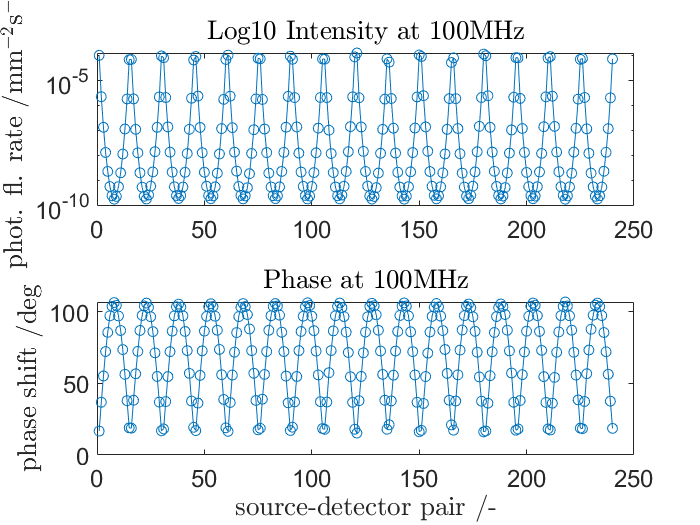


figure('Name',mesh.name)
% plot log intensity at source-detector pairs
subplot(2,1,1); semilogy(data_FD.amplitude,'o-')
title('Log10 Intensity at 100MHz','Interpreter','latex');
ylabel('phot. fl. rate /mm$^{-2}$s$^{-1}$','Interpreter','latex')
% plot phase shift at source-detector pairs
subplot(2,1,2); plot(data_FD.phase,'o-')
title('Phase at 100MHz','Interpreter','latex');
xlabel('source-detector pair /-','Interpreter','latex')
ylabel('phase shift /deg','Interpreter','latex')

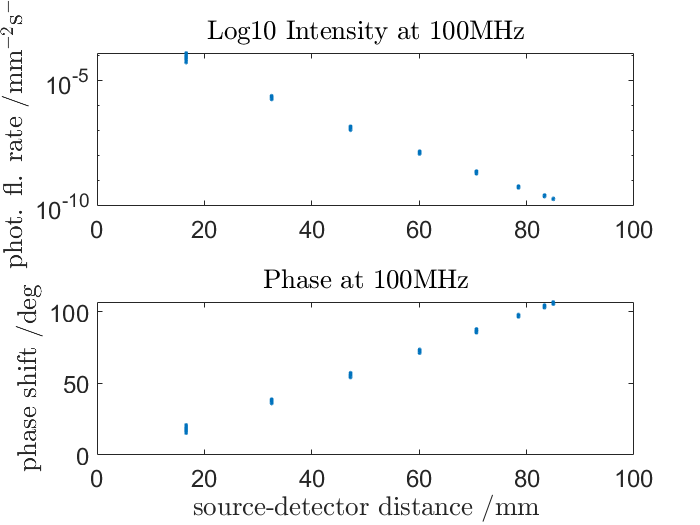


figure('Name',mesh.name)
% plot log intensity vs source-detector distance
subplot(2,1,1); semilogy(sd_distances, data_FD.amplitude,'.')
title('Log10 Intensity at 100MHz','Interpreter','latex');
ylabel('phot. fl. rate /mm$^{-2}$s$^{-1}$','Interpreter','latex')
% plot phase vs source-detector distance
subplot(2,1,2); plot(sd_distances, data_FD.phase,'.')
title('Phase at 100MHz','Interpreter','latex');
xlabel('source-detector distance /mm','Interpreter','latex')
ylabel('phase shift /deg','Interpreter','latex')

## Jacobian 3D

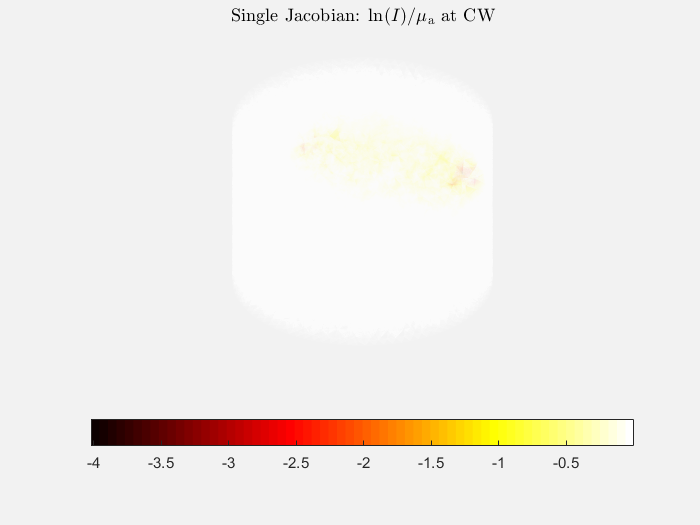

%continuous wave
[J_cw,~] = jacobian_FD(mesh,0);
plotimage(mesh,J_cw.complete(12,:));
title('Single Jacobian: $\ln(I)/\mu_{\mathrm{a}}$ at CW','Interpreter','latex');
alpha(0.1)

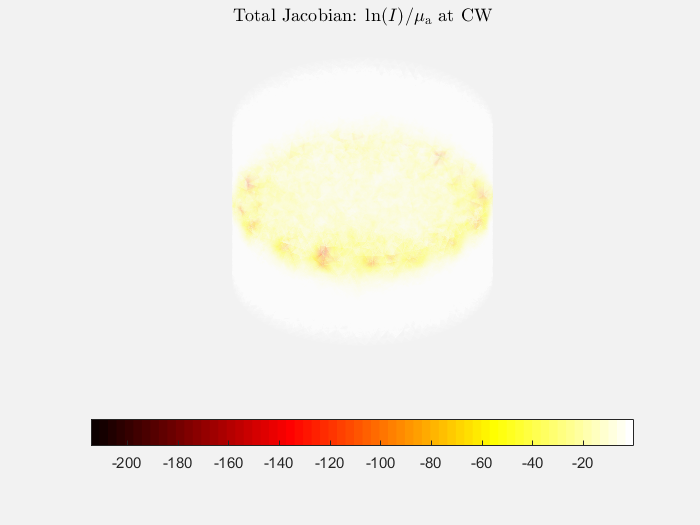

plotimage(mesh,sum(J_cw.complete,1));
title('Total Jacobian: $\ln(I)/\mu_{\mathrm{a}}$ at CW','Interpreter','latex');
alpha(0.1)

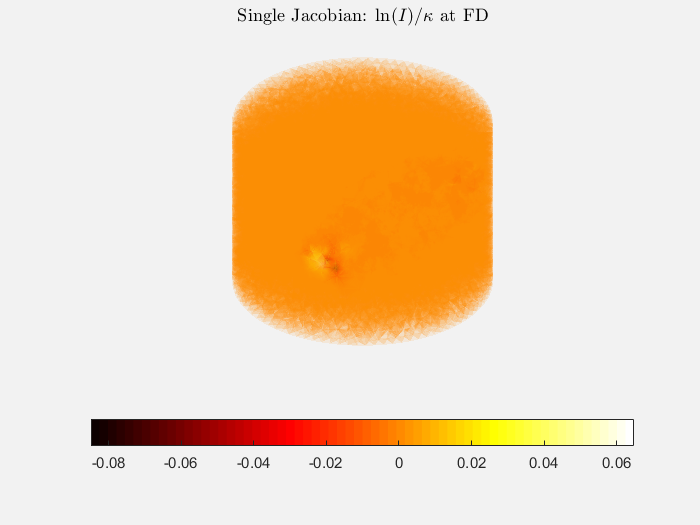


%frequency domain
[J_FD,~] = jacobian_FD(mesh,100e6);
plotimage(mesh,J_FD.complete(11,1:end/2));
title('Single Jacobian: $\ln(I)/\kappa$ at FD','Interpreter','latex');
alpha(0.1)

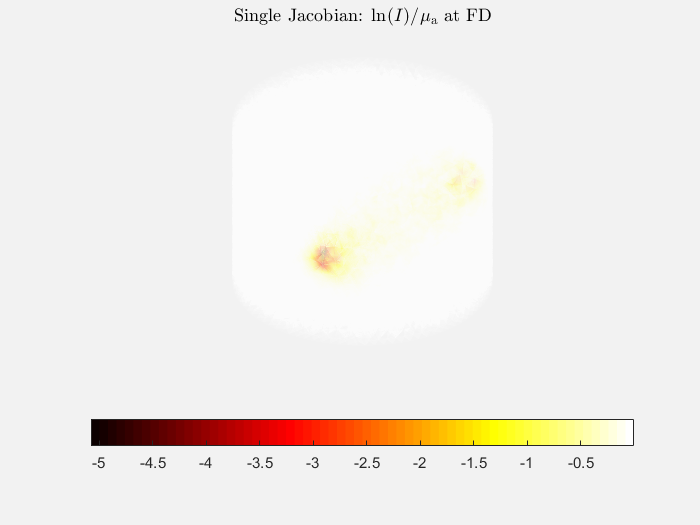

plotimage(mesh,J_FD.complete(11,end/2+1:end));
title('Single Jacobian: $\ln(I)/\mu_{\mathrm{a}}$ at FD','Interpreter','latex');
alpha(0.1)

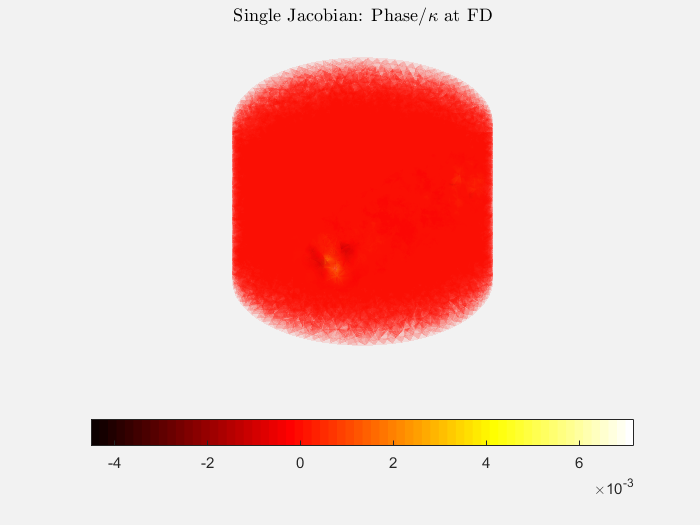

plotimage(mesh,J_FD.complete(12,1:end/2));
title('Single Jacobian: Phase/$\kappa$ at FD','Interpreter','latex');
alpha(0.1)

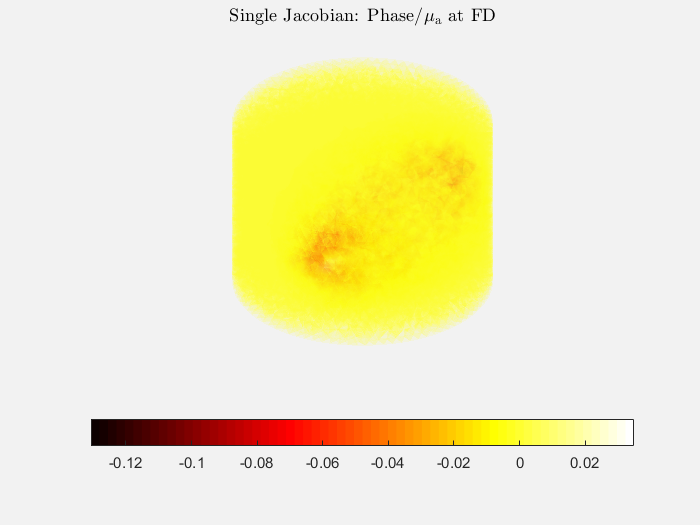

plotimage(mesh,J_FD.complete(12,end/2+1:end));
title('Single Jacobian: Phase/$\mu_{\mathrm{a}}$ at FD','Interpreter','latex');
alpha(0.1)

## test FD on spectral mesh:

## forward data 2D, spectral

mesh = load_mesh('circle2000_86_spec');

Moving Sources
Fixed detectors
Calculating detectors integration functions


## continuous wave 2D, spectral

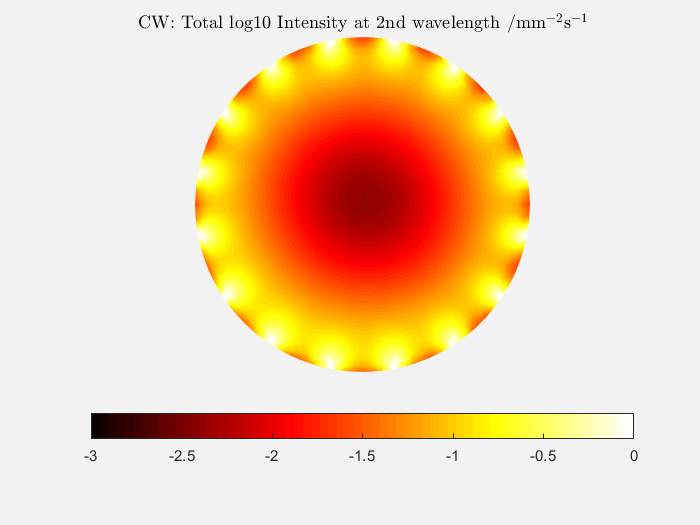

data_cw = femdata_FD(mesh,0);
plotimage(mesh,log10(abs(sum(data_cw.phi(:,:,2),2))));
title('CW: Total log10 Intensity at 2nd wavelength /mm$^{-2}$s$^{-1}$','Interpreter','latex');
set(gca,'CLim',[-3 0])

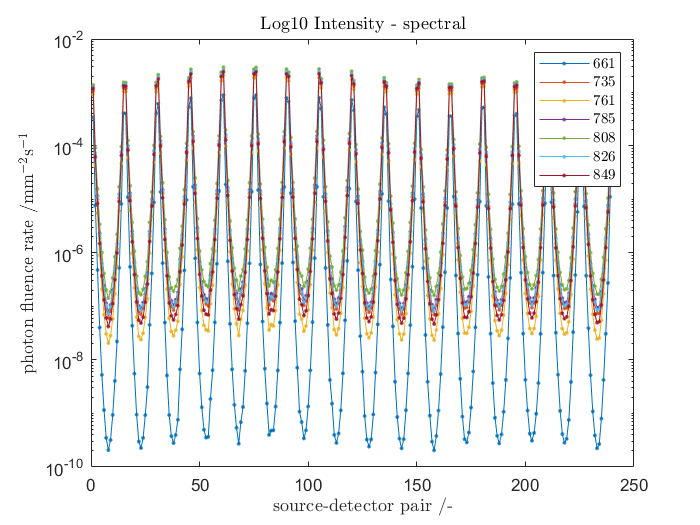


figure('Name',mesh.name)
%plot intensities at source-detector pairs
semilogy(data_cw.amplitude,'.-')
title('Log10 Intensity - spectral','Interpreter','latex');
xlabel('source-detector pair /-','Interpreter','latex')
ylabel('photon fluence rate /mm$^{-2}$s$^{-1}$','Interpreter','latex')
legend(num2str(mesh.wv),'Interpreter','latex')

## frequency domain 2D, spectral

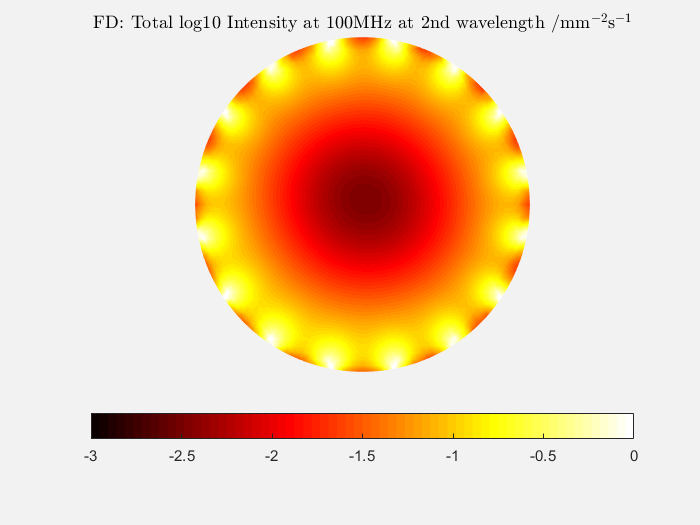

data_FD = femdata_FD(mesh,100e6);
plotimage(mesh,log10(abs(sum(data_FD.phi(:,:,2),2))));
title('FD: Total log10 Intensity at 100MHz at 2nd wavelength /mm$^{-2}$s$^{-1}$','Interpreter','latex');
set(gca,'CLim',[-3 0])

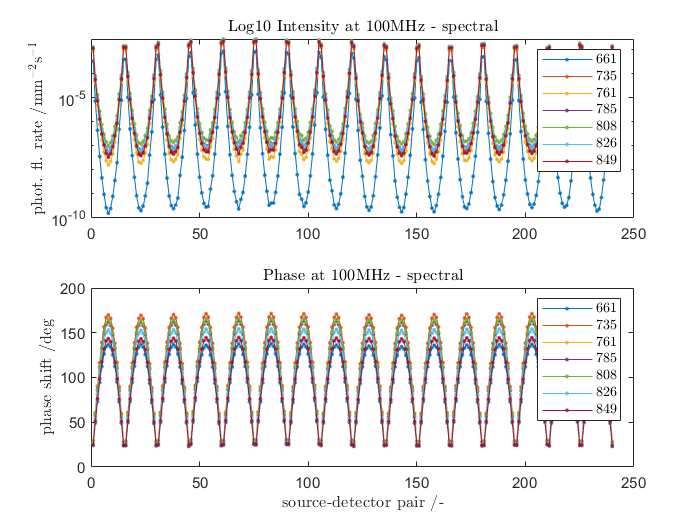


figure('Name',mesh.name)
% plot log intensity at source-detector pairs
subplot(2,1,1); semilogy(data_FD.amplitude,'.-')
title('Log10 Intensity at 100MHz - spectral','Interpreter','latex');
ylabel('phot. fl. rate /mm$^{-2}$s$^{-1}$','Interpreter','latex')
legend(num2str(mesh.wv),'Interpreter','latex')
% plot phase shift at source-detector pairs
subplot(2,1,2); plot(data_FD.phase,'.-')
title('Phase at 100MHz - spectral','Interpreter','latex');
xlabel('source-detector pair /-','Interpreter','latex')
ylabel('phase shift /deg','Interpreter','latex')
legend(num2str(mesh.wv),'Interpreter','latex')

## Jacobian 2D, spectral

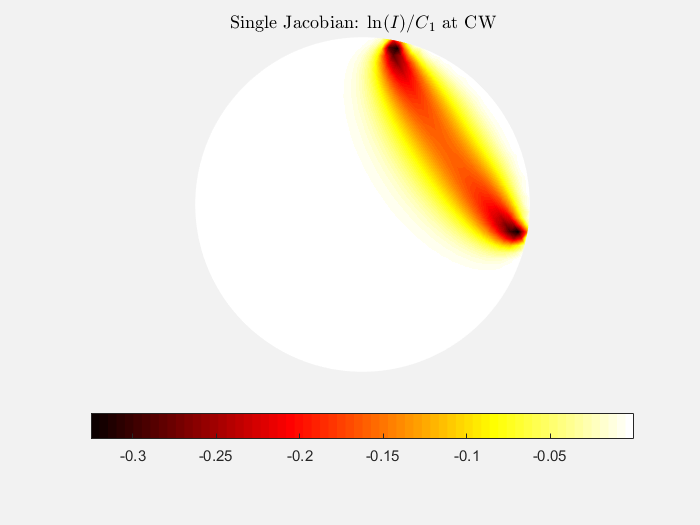

%continuous wave
[J_cw,~] = jacobian_FD(mesh,0);
plotimage(mesh,J_cw(12,1:end/3));
title('Single Jacobian: $\ln(I)/C_{1}$ at CW','Interpreter','latex');

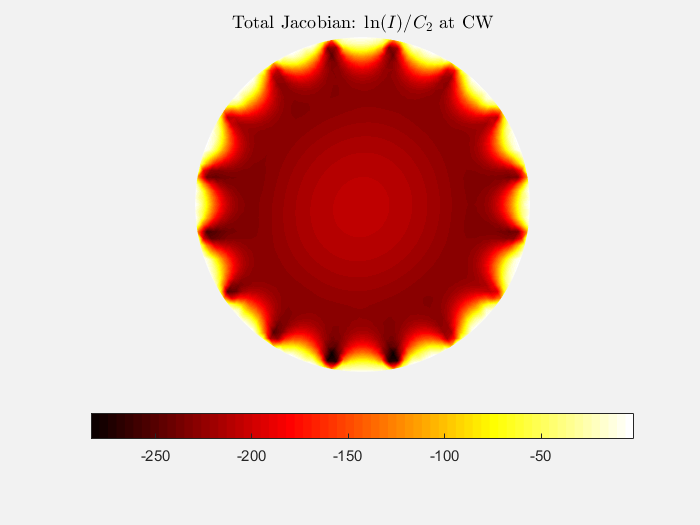

plotimage(mesh,sum(J_cw(:,end/3+1:2*(end/3)),1));
title('Total Jacobian: $\ln(I)/C_{2}$ at CW','Interpreter','latex');

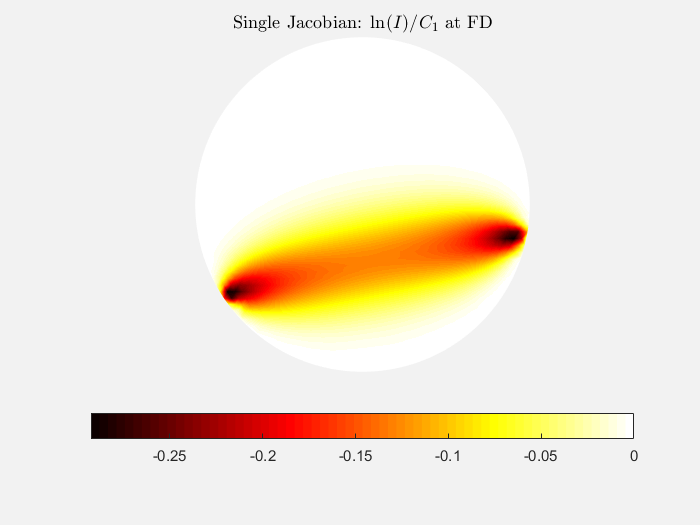


%frequency domain
[J_FD,~] = jacobian_FD(mesh,100e6);
plotimage(mesh,J_FD(11,1:end/5));
title('Single Jacobian: $\ln(I)/C_{1}$ at FD','Interpreter','latex');

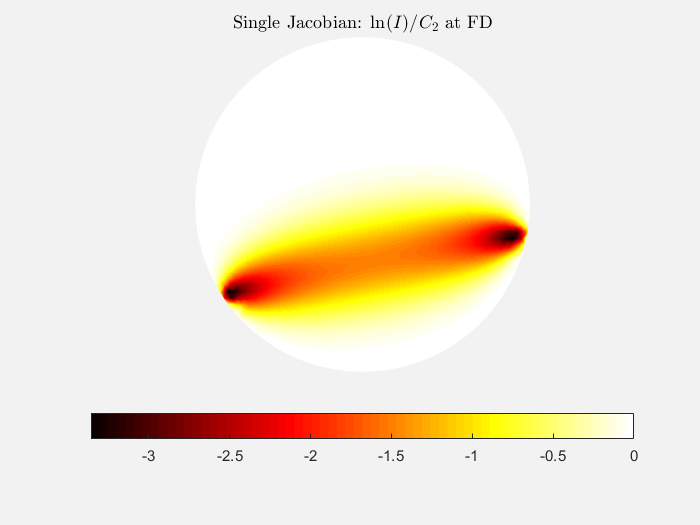

plotimage(mesh,J_FD(11,end/5+1:2*(end/5)));
title('Single Jacobian: $\ln(I)/C_{2}$ at FD','Interpreter','latex');

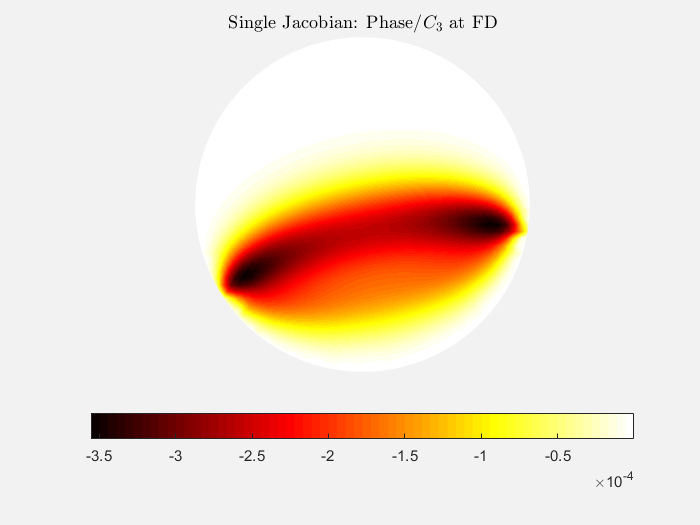

plotimage(mesh,J_FD(12,2*(end/5)+1:3*(end/5)));
title('Single Jacobian: Phase/$C_{3}$ at FD','Interpreter','latex');

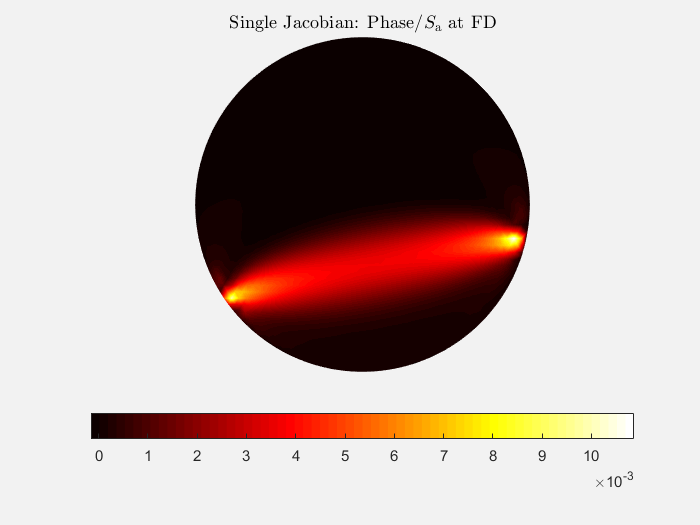

plotimage(mesh,J_FD(12,3*end/5+1:4*(end/5)));
title('Single Jacobian: Phase/$S_{\mathrm{a}}$ at FD','Interpreter','latex');

## forward data 3D, spectral

mesh = load_mesh('cylinder_spec');

Fixed sources
Calculating sources integration functions
Fixed detectors
Calculating detectors integration functions


## continuous wave 3D, spectral

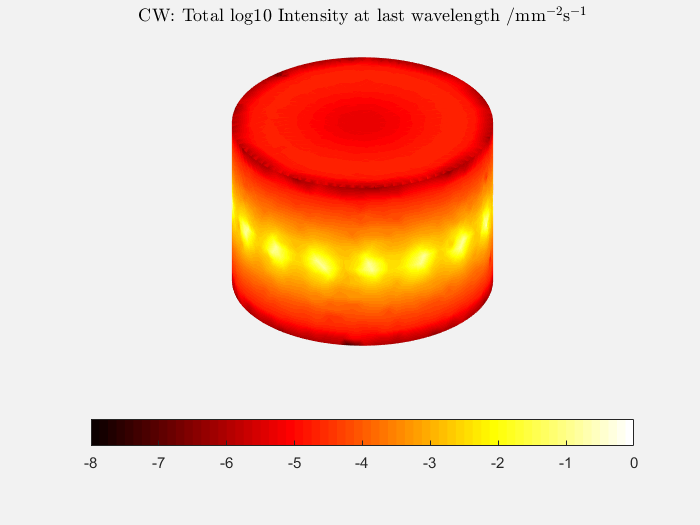

data_cw = femdata_FD(mesh,0);
plotimage(mesh,log10(abs(sum(data_cw.phi(:,:,7),2))));
title('CW: Total log10 Intensity at last wavelength /mm$^{-2}$s$^{-1}$','Interpreter','latex')
set(gca,'CLim',[-8 0])

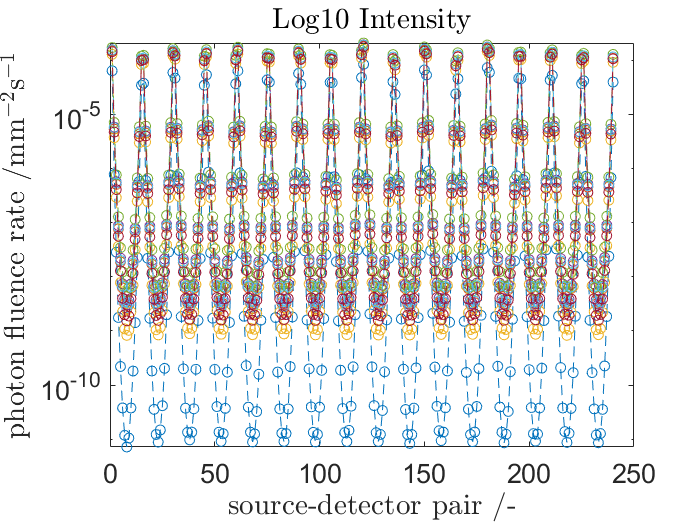


figure('Name',mesh.name)
%plot intensities at source-detector pairs
semilogy(data_cw.amplitude,'o--')
title('Log10 Intensity','Interpreter','latex');
xlabel('source-detector pair /-','Interpreter','latex')
ylabel('photon fluence rate /mm$^{-2}$s$^{-1}$','Interpreter','latex')

## frequency domain 3D, spectral

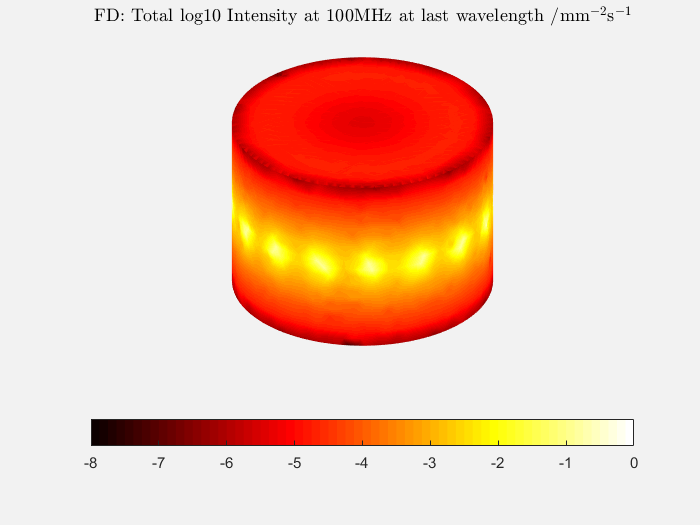

data_FD = femdata_FD(mesh,100e6);
plotimage(mesh,log10(abs(sum(data_FD.phi(:,:,7),2))));
title('FD: Total log10 Intensity at 100MHz at last wavelength /mm$^{-2}$s$^{-1}$','Interpreter','latex');
set(gca,'CLim',[-8 0])

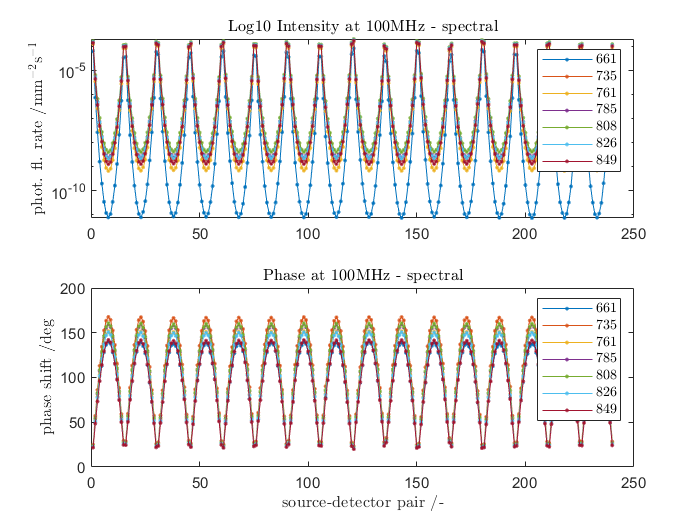


figure('Name',mesh.name)
% plot log intensity at source-detector pairs
subplot(2,1,1); semilogy(data_FD.amplitude,'.-')
title('Log10 Intensity at 100MHz - spectral','Interpreter','latex');
ylabel('phot. fl. rate /mm$^{-2}$s$^{-1}$','Interpreter','latex')
legend(num2str(mesh.wv),'Interpreter','latex')
% plot phase shift at source-detector pairs
subplot(2,1,2); plot(data_FD.phase,'.-')
title('Phase at 100MHz - spectral','Interpreter','latex');
xlabel('source-detector pair /-','Interpreter','latex')
ylabel('phase shift /deg','Interpreter','latex')
legend(num2str(mesh.wv),'Interpreter','latex')

## Jacobian 3D, spectral

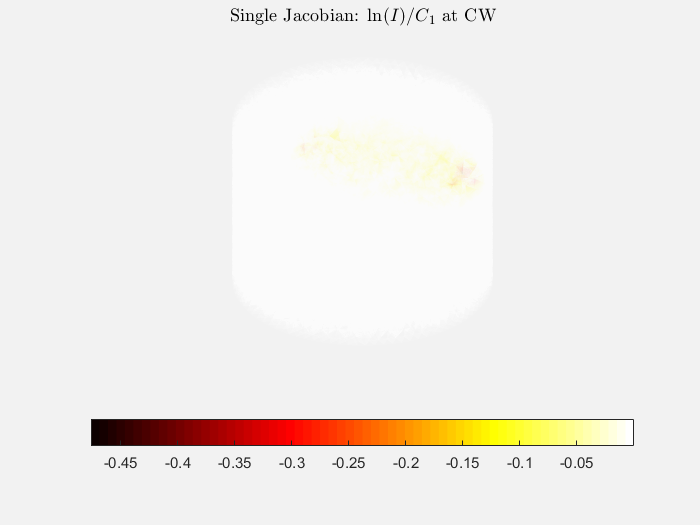

%continuous wave
[J_cw,~] = jacobian_FD(mesh,0);
plotimage(mesh,J_cw(12,1:end/3));
title('Single Jacobian: $\ln(I)/C_{1}$ at CW','Interpreter','latex');
alpha(0.1)

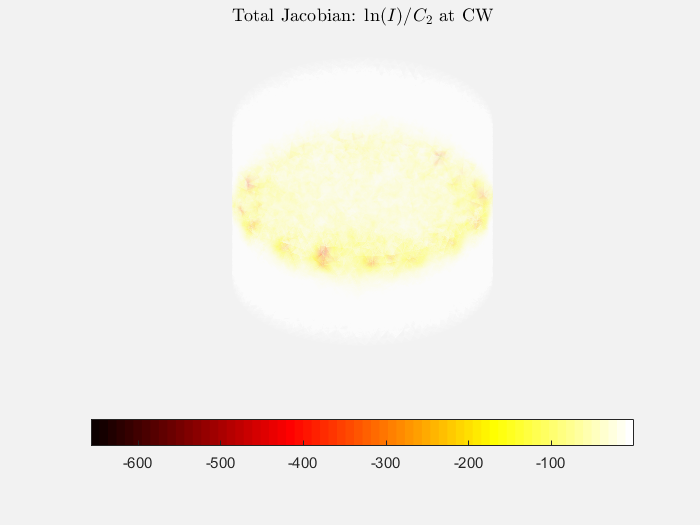

plotimage(mesh,sum(J_cw(:,end/3+1:2*(end/3)),1));
title('Total Jacobian: $\ln(I)/C_{2}$ at CW','Interpreter','latex');
alpha(0.1)

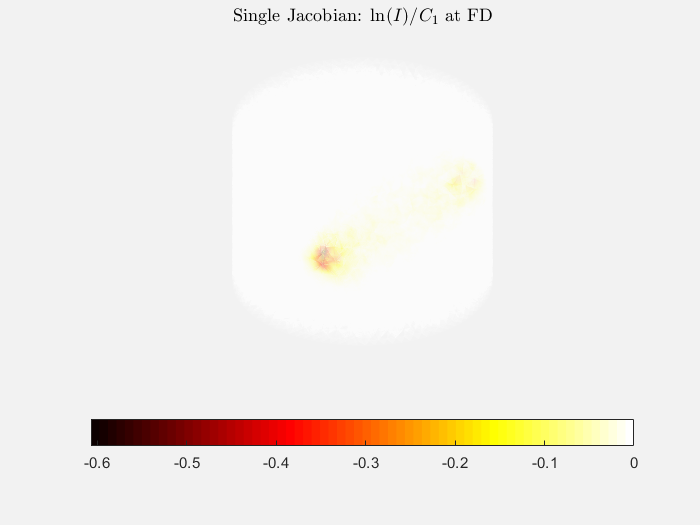


%frequency domain
[J_FD,~] = jacobian_FD(mesh,100e6);
plotimage(mesh,J_FD(11,1:end/5));
title('Single Jacobian: $\ln(I)/C_{1}$ at FD','Interpreter','latex');
alpha(0.1)

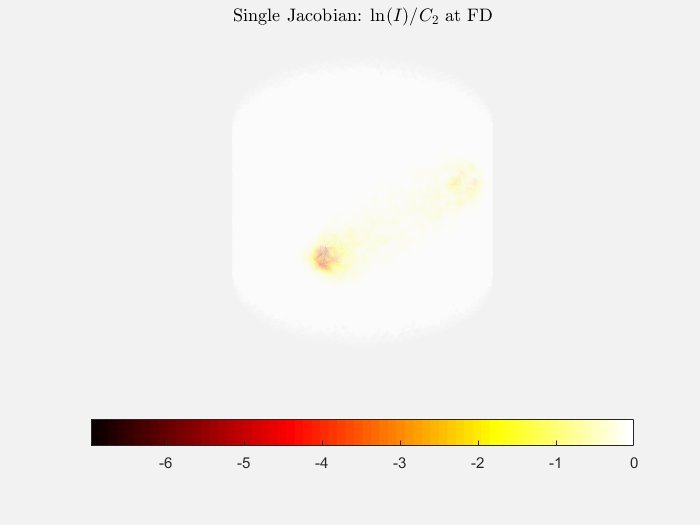

plotimage(mesh,J_FD(11,end/5+1:2*(end/5)));
title('Single Jacobian: $\ln(I)/C_{2}$ at FD','Interpreter','latex');
alpha(0.1)

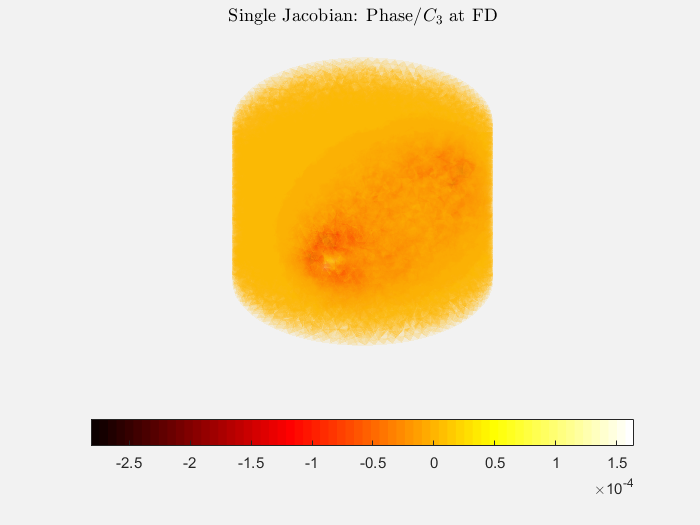

plotimage(mesh,J_FD(12,2*(end/5)+1:3*(end/5)));
title('Single Jacobian: Phase/$C_{3}$ at FD','Interpreter','latex');
alpha(0.1)

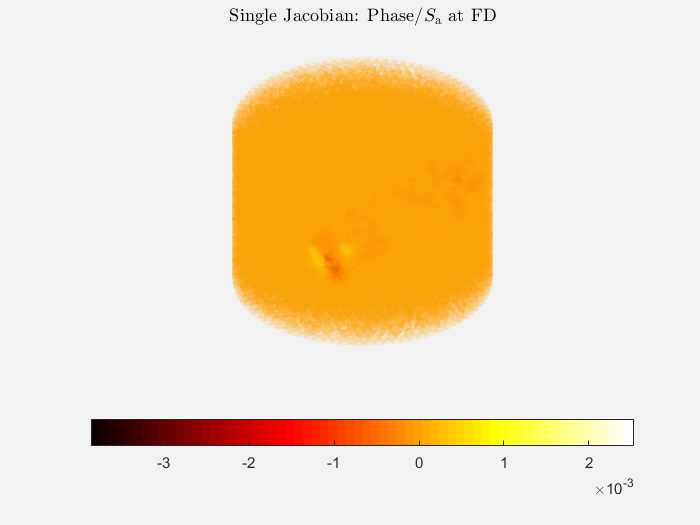

plotimage(mesh,J_FD(12,3*end/5+1:4*(end/5)));
title('Single Jacobian: Phase/$S_{\mathrm{a}}$ at FD','Interpreter','latex');
alpha(0.1)